# Find Threshold and Segment Dark Text from Bright Background

Read image into the workspace.

I = imread('printedtext.png');

Using `adaptthresh` compute adaptive threshold and display the local threshold image. This represents an estimate of average background illumination.

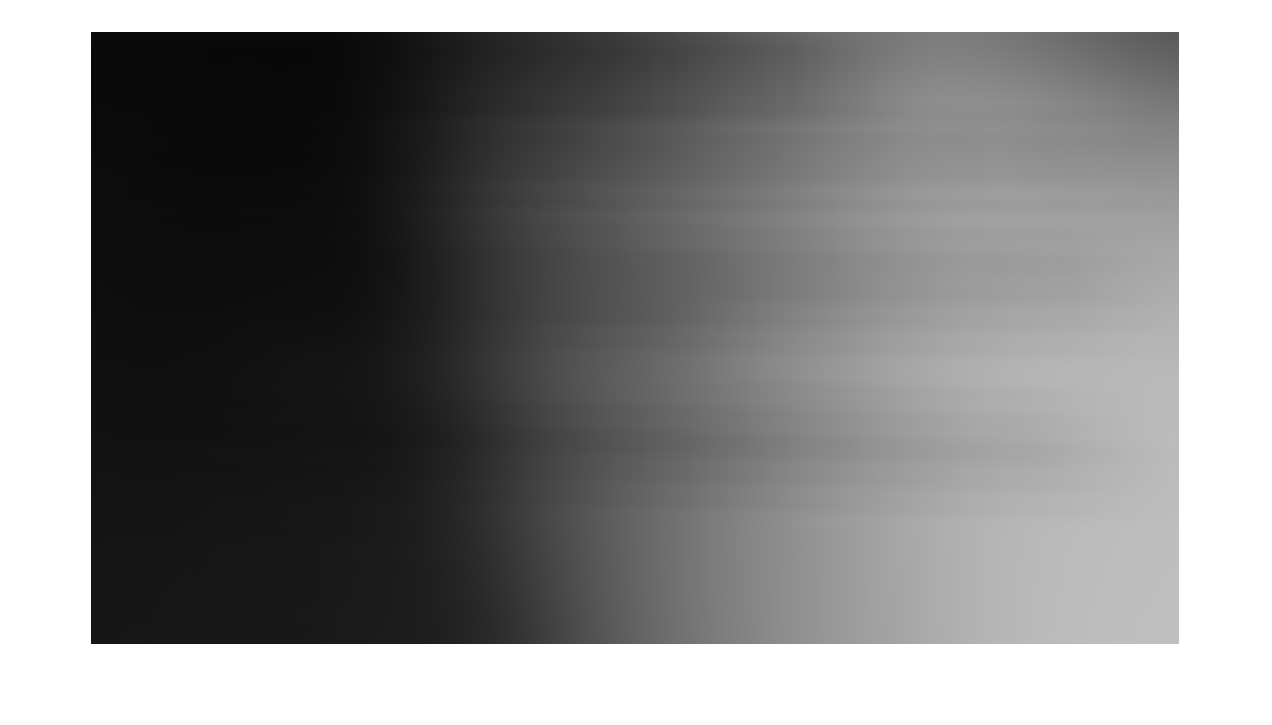

T = adaptthresh(I,0.4,'ForegroundPolarity','dark');
figure
imshow(T)

Binarize image using locally adaptive threshold

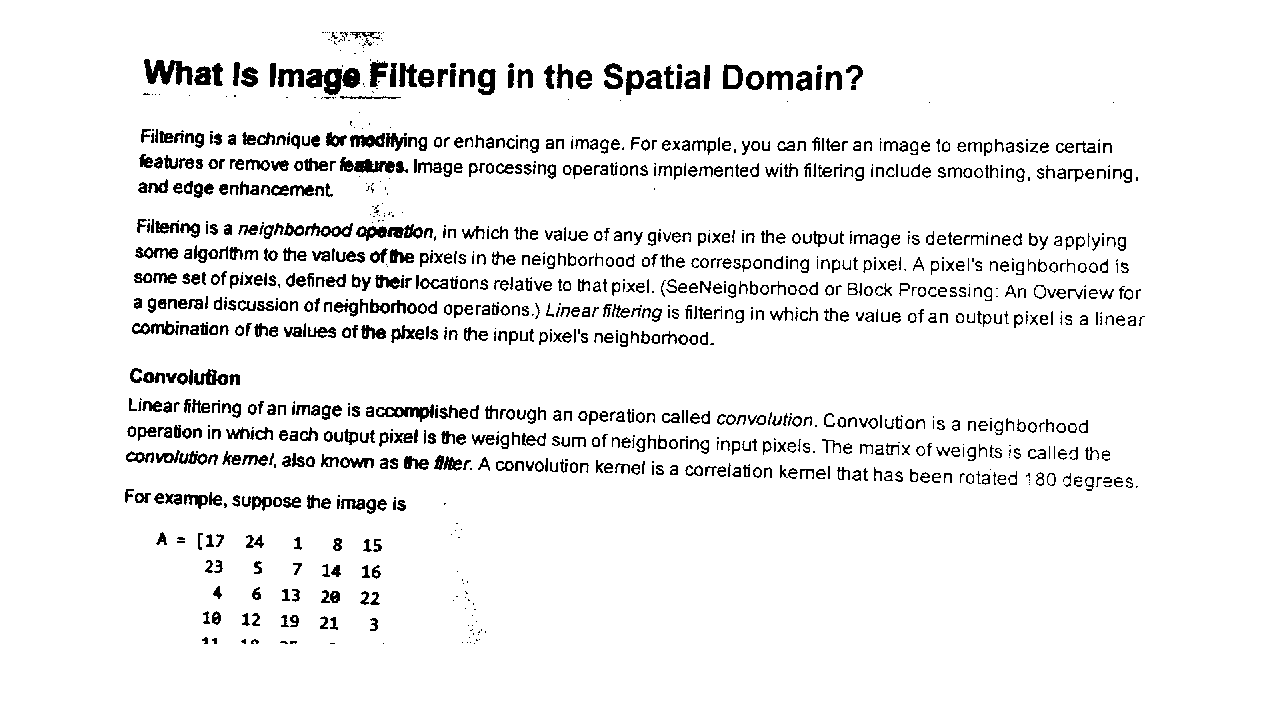

BW = imbinarize(I,T);
figure
imshow(BW)